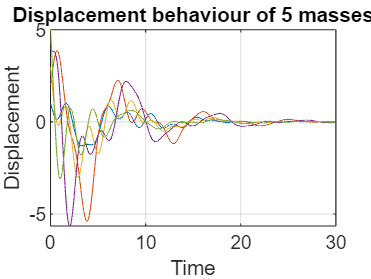

k = 1; % stiffness
d = 0.3; % damping factor
massMatrix = [1, 2, 1, 2, 1]; % mass values of all masses
N = length(massMatrix); % how many masses there are
X0 = [1 2 3 4 5 -1 2 -3 -1 -5]'; % should be 2N values (3 displacements and 3 velocities, all displacements first)
T = 30;
tstep = 0.001;
tbounds = [0 T];
tarray = tbounds(1):tstep:tbounds(2);

topLeft = zeros(N, N);
    topRight = eye(N,N);
    % defining bottom left
% but for a large matrix
bottomLeft = diag(-2*k*ones(1,N), 0)./massMatrix + diag(k*ones(1,N-1), -1)./massMatrix + diag(k*ones(1, N-1), 1)./massMatrix;
bottomRight = diag(-d*ones(1,N), 0)./massMatrix;

topHalf = horzcat(topLeft, topRight);
P = vertcat(topHalf, horzcat(bottomLeft, bottomRight)); % system matrix

xS = zeros(length(tarray),2*N)';% Same reason as line 5, each column would be a solution at each time step for all masses

% horizontal direction is "time axis"
% columns are the solutions for displacements and velocities
xS(:,1) = X0; % Setting first column as initial condition

% Runge Kutta
for i = 2:length(tarray)
    k1 = tstep*P*xS(:,i-1);
    k2 = tstep*P*xS(:,i-1) + k1/2;
    k3 = tstep*P*xS(:,i-1) + k2/2;
    k4 = tstep*P*xS(:,i-1) + k3;
    xS(:, i) = xS(:,i-1) + k1/6 + (k2+k3)/3 + k4/6;
    xS(:,i-1) = xS(:, i);
end

hold off
for i = 1:size(xS, 1)/2
    plot(tarray, xS(i,:))
    hold on
    grid on
end
xlabel("Time")
ylabel("Displacement")
title("Displacement behaviour of 5 masses")

hold off

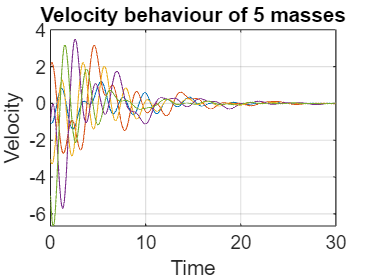

for i = 1:size(xS, 1)/2

    plot(tarray, xS(i+size(xS,1)/2,:))
    hold on
    grid on
end
xlabel("Time")
ylabel("Velocity")
title("Velocity behaviour of 5 masses")